# Trabajo grupal 2 (Métodos Numéricos)

- Sección: 5

- N° de grupo: 2

- Integrante 1 (líder): Carlos Fabrizio Condor Hurtado 202510436- 100%        

- Integrante 2: Paula del Pilar Vértiz Puémape 202510115 - 100%

- Integrante 3: Alejandra Brisa SIlva Salazar 202510586- 100%

- Integrante 4:Sanchez Silvera Joseph 202510025- 100%

- Integrante 5:Carlos Alberto Zavalaga Hilasaca -202510095 - 100%

**Observación:** No olvidar añadir el porcentaje de participación.

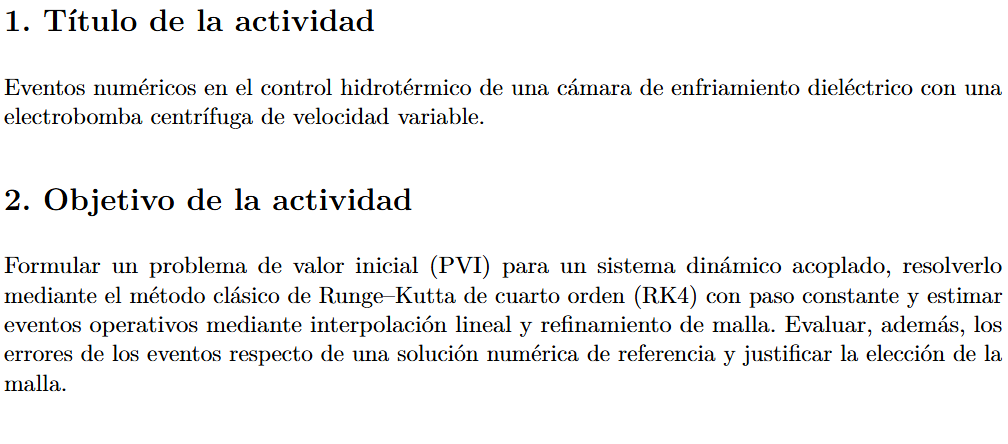

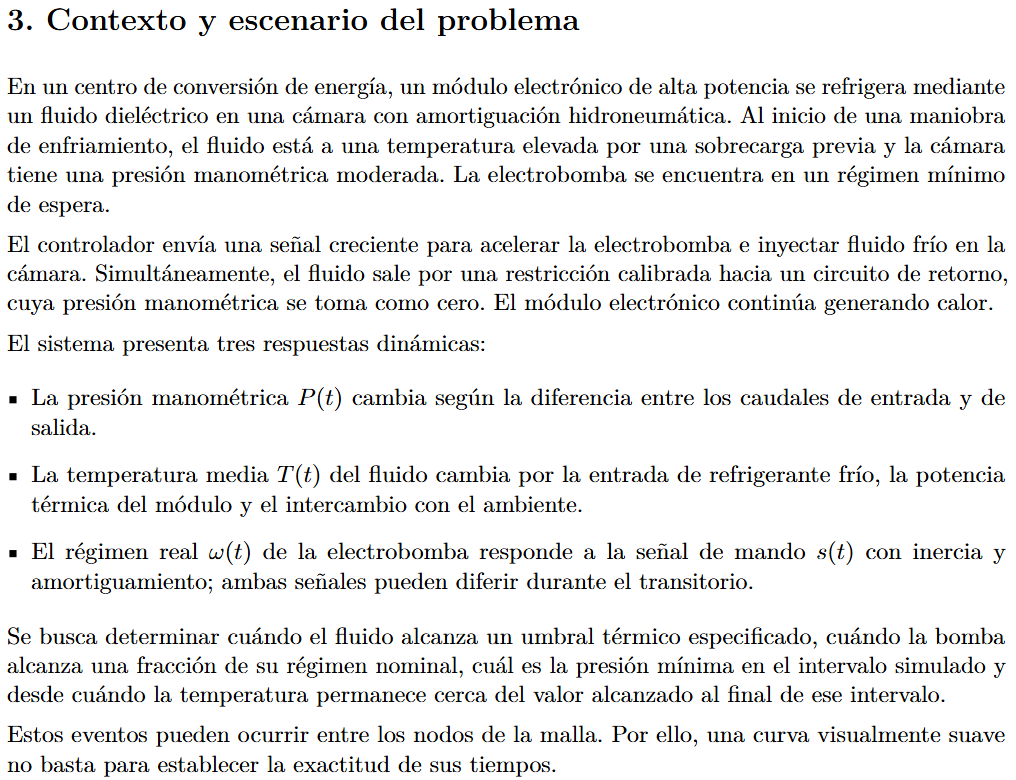

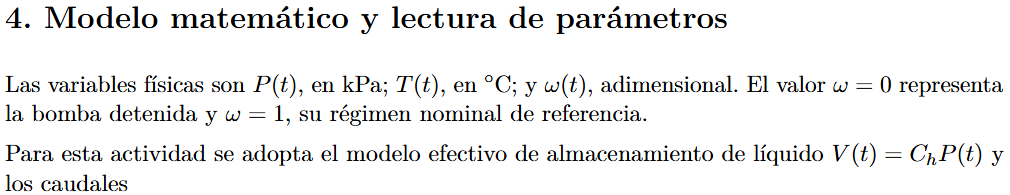

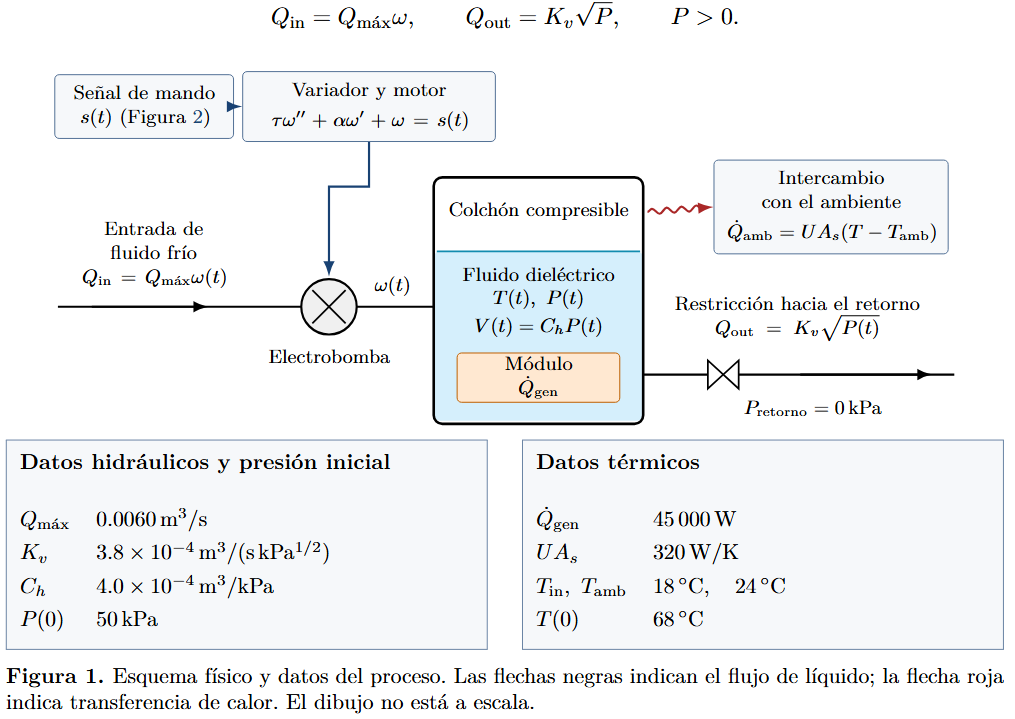

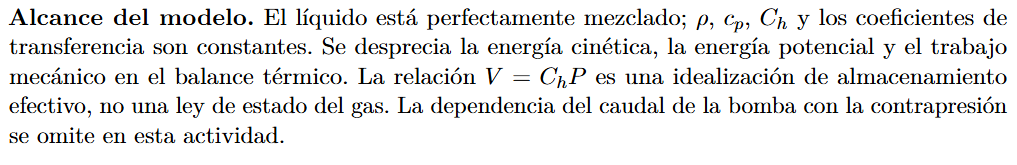

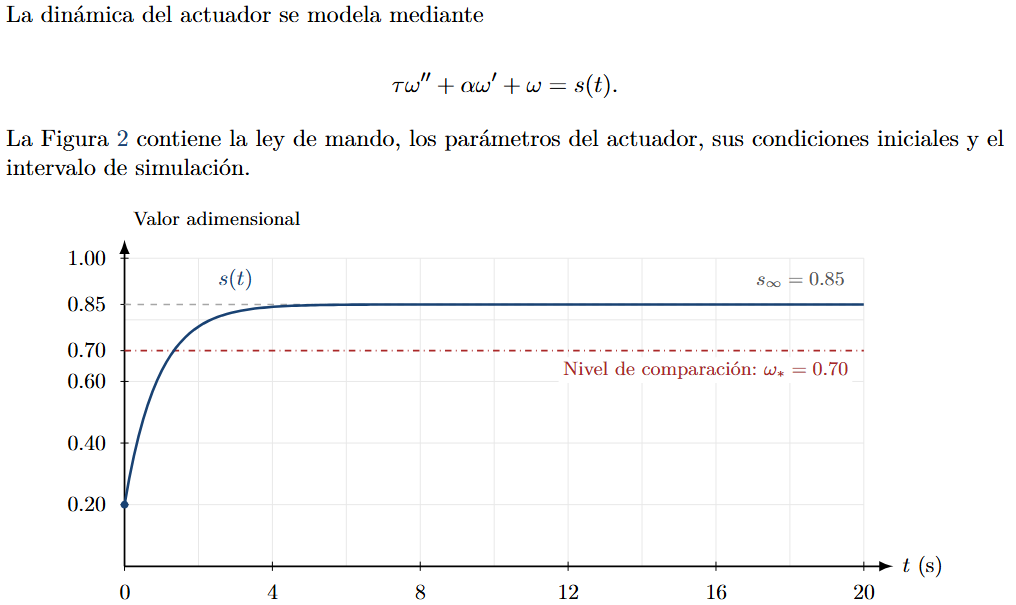

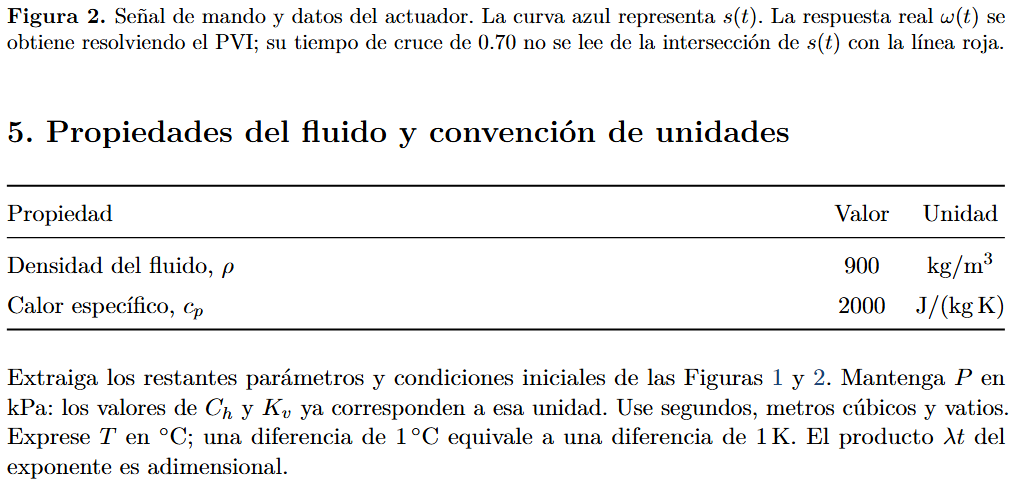

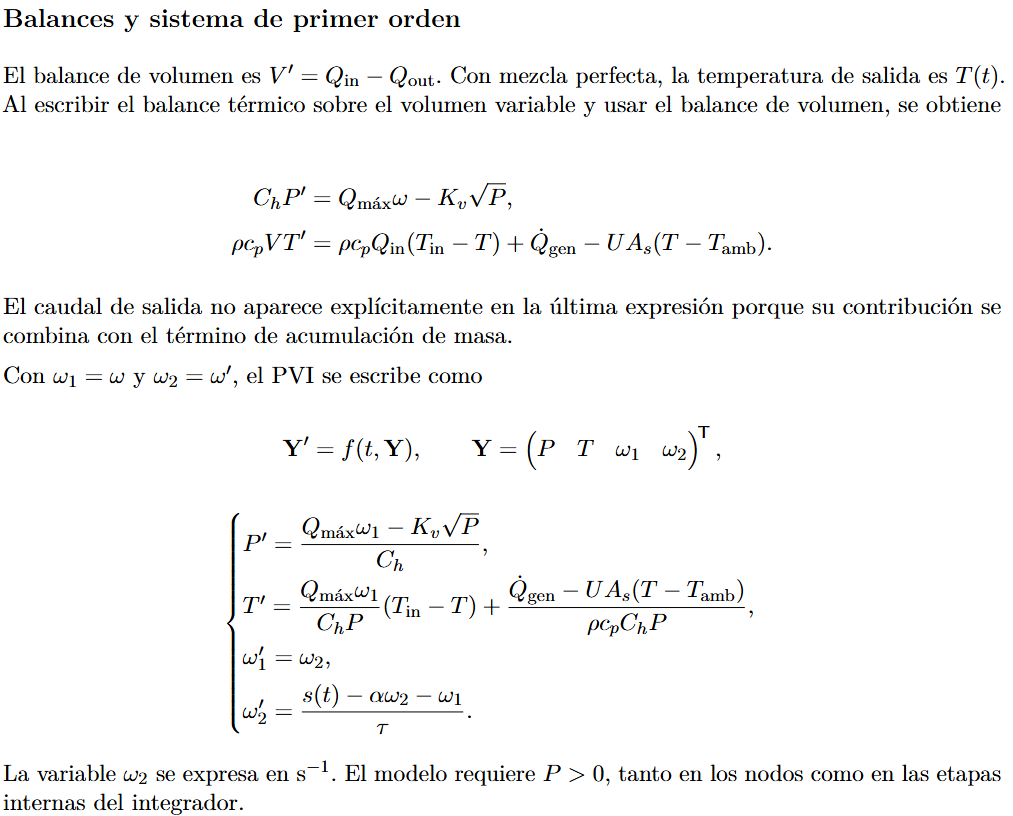

clearvars; clc; close all;

p.Qmax  = 0.0060;    
p.Kv    = 3.8e-4;   
p.Ch    = 4.0e-4;   
p.Qgen  = 45000;     
p.UAs   = 320;      
p.Tin   = 18;        
p.Tamb  = 24;        
p.rho   = 900;       
p.cp    = 2000;      
p.s0    = 0.20;      
p.ds    = 0.65;
p.lam   = 1.10;      
p.tau   = 0.80;     
p.alpha = 1.10;     

t0 = 0;  tf = 20;                 
Y0 = [50; 68; 0.20; 0];           
Ns = [50 100 200 400 800];        

P'  = 15.0000*w1 - 0.9500*sqrt(P)


DT = 0.5;                        
Tumbral = 42;  wumbral = 0.70;    

T'  = [15.0000*w1*(18 - T) + 62.5000 - 0.444444*(T - 24)]/P


w1' = w2


f = @(t,Y) edo_rc02(t,Y,p);

w2' = 1.2500*s(t) - 1.3750*w2 - 1.2500*w1


cV = p.rho*p.cp*p.Ch;             

s(t) = 0.20 + 0.65*(1 - exp(-1.10*t))


fprintf('P''  = %.4f*w1 - %.4f*sqrt(P)\n', p.Qmax/p.Ch, p.Kv/p.Ch);
fprintf('T''  = [%.4f*w1*(%.0f - T) + %.4f - %.6f*(T - %.0f)]/P\n', ...

Y(0) = [P; T; w1; w2] =
   50.0000
   68.0000
    0.2000
         0



        p.Qmax/p.Ch, p.Tin, p.Qgen/cV, p.UAs/cV, p.Tamb);

f(0,Y(0)) =
   -3.7175
   -2.1411
         0
         0



fprintf('w1'' = w2\n');
fprintf('w2'' = %.4f*s(t) - %.4f*w2 - %.4f*w1\n', 1/p.tau, p.alpha/p.tau, 1/p.tau);
fprintf('s(t) = %.2f + %.2f*(1 - exp(-%.2f*t))\n', p.s0, p.ds, p.lam);

disp('Y(0) = [P; T; w1; w2] ='); disp(Y0)
disp('f(0,Y(0)) ='); disp(f(0,Y0))

**1. Significado de los eventos**

tT42 corresponde al primer cruce descendente de 42 °C debido al ingreso de líquido frío, mientras que tω70 indica el primer cruce ascendente de ω = 0.70, considerando la inercia de la bomba mediante el PVI. Por su parte, tP,mín representa la presión mínima global en [t₀, t_f], que ocurre cuando se igualan los caudales (P′ = 0), y test,T indica desde cuándo la temperatura permanece dentro de ±0.5 K respecto a T(t_f), sin que esto implique necesariamente un equilibrio definitivo.

**2. Deducción de la fórmula para t*_lin**

Para encontrar el instante en que la variable alcanza el umbral y*, se iguala la interpolación lineal a dicho valor y luego se despeja el tiempo:

L(t) = y*

yᵢ + [(yᵢ₊₁ − yᵢ)/(tᵢ₊₁ − tᵢ)] · (t − tᵢ) = y*

t*_lin = tᵢ + [(y* − yᵢ)/(yᵢ₊₁ − yᵢ)] · (tᵢ₊₁ − tᵢ)

La condición (yᵢ − y*)(yᵢ₊₁ − y*) < 0 garantiza que los puntos están a lados opuestos del umbral, que yᵢ₊₁ ≠ yᵢ y que la fracción está entre 0 y 1; por eso, el cruce queda dentro del intervalo.

**3. Dirección del cruce y casos especiales**

El cruce es descendente cuando yᵢ > y* > yᵢ₊₁ y ascendente cuando yᵢ < y* < yᵢ₊₁, lo cual también se identifica observando si la diferencia yᵢ₊₁ − yᵢ es negativa o positiva. Si el umbral coincide con un nodo, este se asigna al intervalo que termina en él, usando intervalos semiabiertos, para evitar contarlo dos veces; además, se debe cumplir yᵢ₊₁ ≠ yᵢ para aplicar la fórmula. Si la variable solo toca el umbral sin atravesarlo, no existe un cruce, y si todo el segmento permanece sobre él, tampoco hay un instante único.

**4. Error del integrador frente al de interpolación**

Para una solución suficientemente suave, RK4 presenta un error global de orden O(h⁴), mientras que la interpolación lineal tiene un error de orden O(h²), incluso si los puntos son exactos. Por ello, en un cruce simple, donde y′(t*) ≠ 0, se espera que el error del tiempo de cruce sea O(h²), es decir, que al reducir h a la mitad disminuya aproximadamente cuatro veces. Esto también explica por qué una gráfica puede verse suave sin garantizar tiempos precisos: un pequeño error δy puede generar un cambio importante en el tiempo, según δt ≈ δy/|y′(t*)|, especialmente cuando la pendiente en el cruce es pequeña.

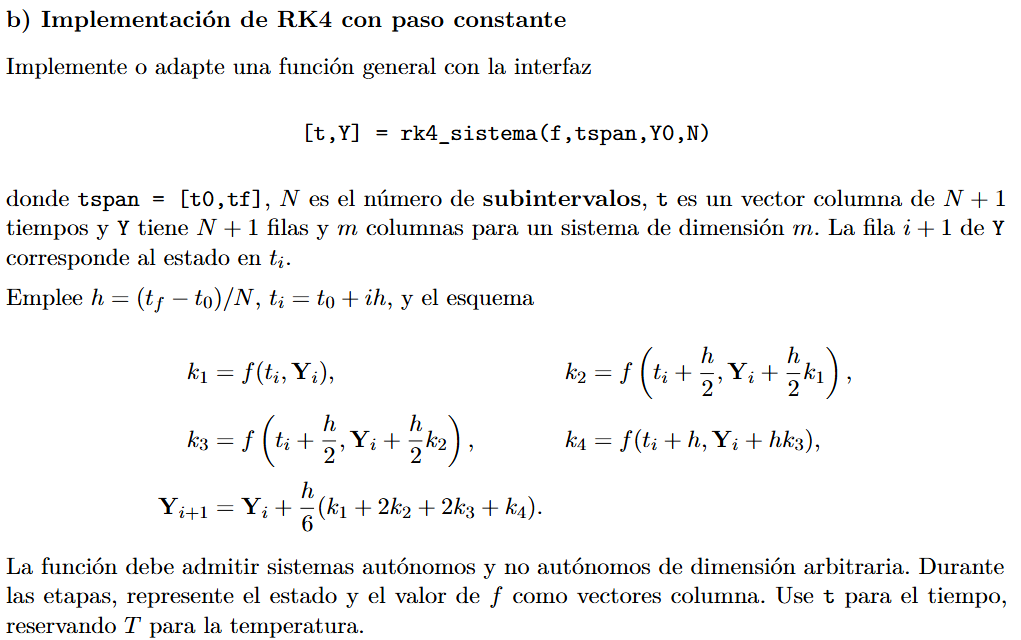

function [t,Y] = rk4_sistema(f,tspan,Y0,N)
    t0 = tspan(1);
    tf = tspan(2);
    h = (tf-t0)/N;
    m = length(Y0);
    t = linspace(t0,tf,N+1)';
    Y = zeros(N+1,m);

    %cond inicial planteada anteriormente en integrante 1
    Y(1,:) = Y0(:)';
   %RK 4to orden
    for i = 1:N
        ti = t(i);
        Yi = Y(i,:)';

        k1 = f(ti,Yi);
        k1 = k1(:);

        k2 = f(ti+h/2,Yi+(h/2)*k1);
        k2 = k2(:);

        k3 = f(ti+h/2,Yi+(h/2)*k2);
        k3 = k3(:);

        k4 = f(ti+h,Yi+h*k3);
        k4 = k4(:);

        Y(i+1,:) = (Yi+(h/6)*(k1+2*k2+2*k3+k4))';

    end
end

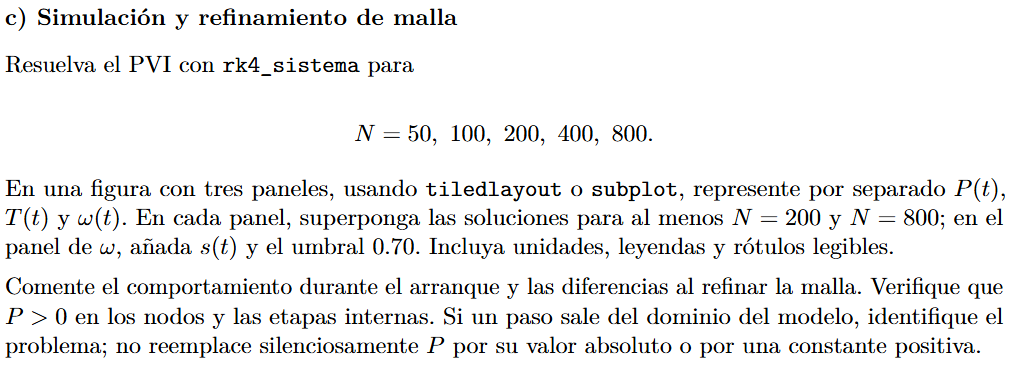

tspan = [t0, tf];
tN = cell(length(Ns),1);
YN = cell(length(Ns),1);
for j = 1:length(Ns)
    N = Ns(j);
    [t,Y] = rk4_sistema(f, tspan, Y0, N);

    tN{j} = t;
    YN{j} = Y;
end

t200 = tN{3};
Y200 = YN{3};

t800 = tN{5};
Y800 = YN{5};

s = @(t) 0.20 + 0.65*(1-exp(-1.10*t));
fig = figure('Visible','off');
tiledlayout(fig,3,1)

%panel de P de presion (pedido arriba en el enunciado)
nexttile
plot(t200,Y200(:,1),'b','LineWidth',1.5)
hold on
plot(t800,Y800(:,1),'r--','LineWidth',1.5)
xlabel('Tiempo (s)')
ylabel('Presion (kPa)')
title('Presion de la camara')
legend('N=200','N=800')
grid on

%grafica de T de temperatura
nexttile
plot(t200,Y200(:,2),'b','LineWidth',1.5)
hold on
plot(t800,Y800(:,2),'r--','LineWidth',1.5)
xlabel('Tiempo (s)')
ylabel('Temperatura (°C)')
title('Temperatura del fluido')
legend('N=200','N=800')
grid on

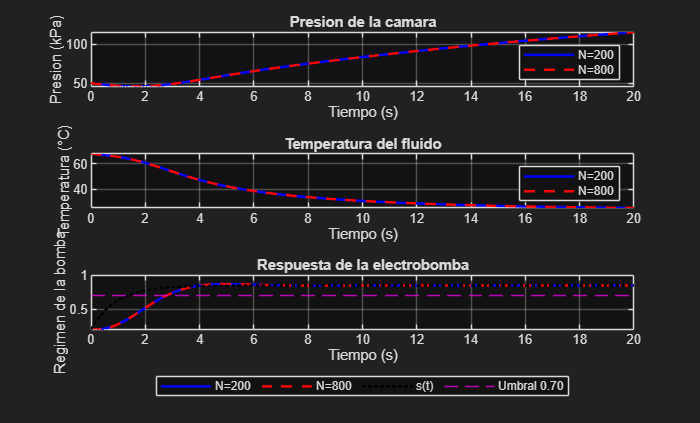

%grafica de w de regimen de la bomba propuesta
nexttile
plot(t200,Y200(:,3),'b','LineWidth',1.5)
hold on
plot(t800,Y800(:,3),'r--','LineWidth',1.5)
plot(t800,s(t800),'k:','LineWidth',1.5)
yline(0.70,'m--')
xlabel('Tiempo (s)')
ylabel('Regimen de la bomba')
title('Respuesta de la electrobomba')
legend('N=200','N=800','s(t)','Umbral 0.70', ...

       'Location','southoutside','Orientation','horizontal')
grid on
fig.Visible = 'on';

%verificando si hay presiones positivas o no con una tabla
hvalores = zeros(length(Ns),1);
Pmin = zeros(length(Ns),1);
positiva = false(length(Ns),1);

for j = 1:length(Ns)
    N = Ns(j);

    hvalores(j) = (tf-t0)/N;
    Pmin(j) = min(YN{j}(:,1));
    positiva(j) = all(YN{j}(:,1)>0);
end

tablaPresion = table(Ns',hvalores,Pmin,positiva, ...
    'VariableNames',{'N','h','Pmin','PresionPositiva'});

     N       h       Pmin     PresionPositiva
    ___    _____    ______    _______________

     50      0.4    45.951         true      
    100      0.2    45.951         true      
    200      0.1    45.949         true      
    400     0.05    45.945         true      
    800    0.025    45.945         true      




disp(tablaPresion);

%ultima verificacion explicita como terminaron todos los nodos
if all(positiva)
    disp('P > 0 en todos los nodos.');
    disp('Las etapas internas de RK4 se evaluaron sin errores de dominio.');
else
    error('Se encontraron presiones no positivas en los nodos.');

P > 0 en todos los nodos.


Las etapas internas de RK4 se evaluaron sin errores de dominio.


end

**Discusión del comportamiento durante el arranque y refinamiento de malla**

Durante el intervalo de simulación de 0 a 20 s, la presión parte de 50 kPa, disminuye hasta aproximadamente 45.95 kPa y posteriormente aumenta hasta valores cercanos a 116 kPa. Este comportamiento se relaciona con el incremento progresivo del régimen de la electrobomba, que pasa de 0.20 a aproximadamente 0.85, siguiendo con cierto retraso la señal de mando. Paralelamente, la temperatura disminuye desde 68 °C hasta aproximadamente 25 °C, evidenciando el enfriamiento del fluido.

Respecto al refinamiento de malla, las soluciones obtenidas con N = 200 (h = 0.1 s) y N = 800 (h = 0.025 s) presentan curvas prácticamente superpuestas en las tres variables, lo que indica diferencias visuales pequeñas. Además, la presión mínima calculada pasa de 45.949 kPa a 45.945 kPa, una diferencia de apenas 0.004 kPa. Finalmente, se verificó que P > 0 en todos los nodos y etapas internas de RK4 para las cinco mallas, sin detectar salidas del dominio del modelo.

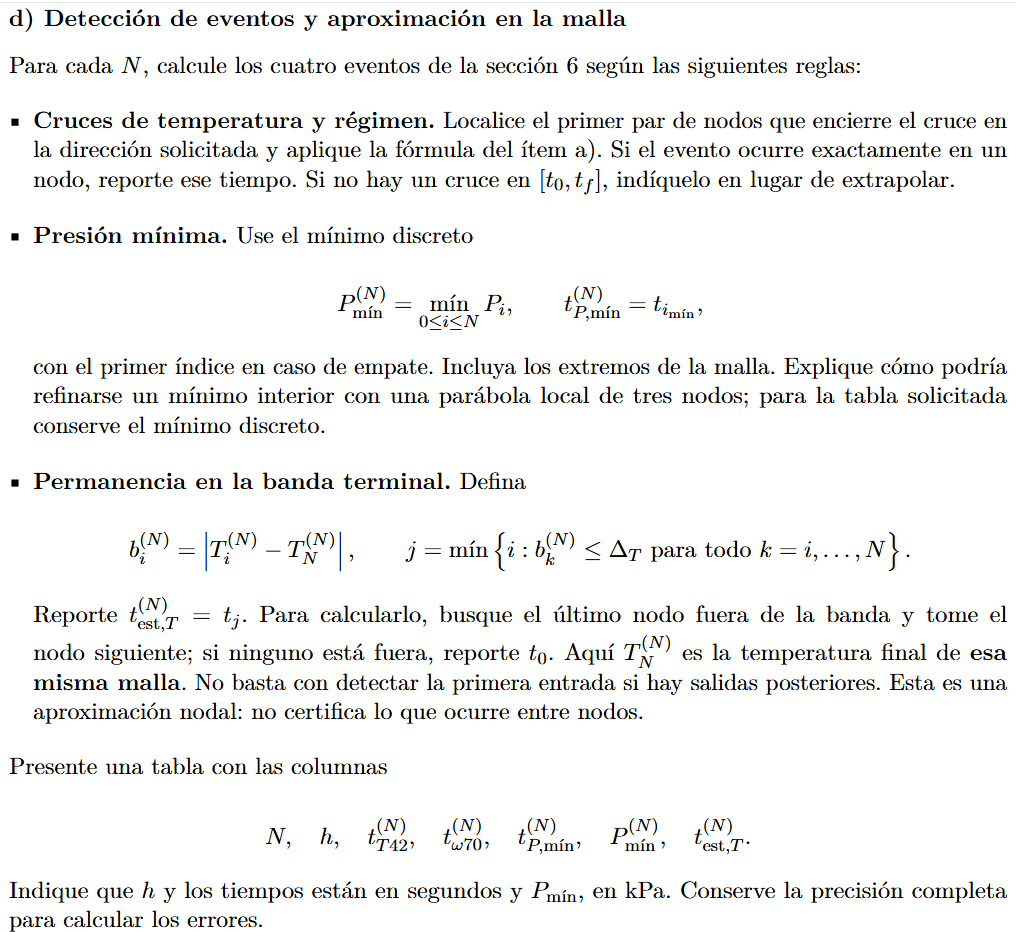

nN   = numel(Ns);
hv   = (tf - t0)./Ns(:);              
tT42 = zeros(nN,1);  tw70 = zeros(nN,1);  tPmin = zeros(nN,1);
Pmn  = zeros(nN,1);  test = zeros(nN,1);

for j = 1:nN
    t = tN{j};  P = YN{j}(:,1);  T = YN{j}(:,2);  w = YN{j}(:,3);

    tT42(j) = cruce_lineal(t,T,Tumbral,'desc');  
    tw70(j) = cruce_lineal(t,w,wumbral,'asc');    

    [Pmn(j),imin] = min(P);                       
    tPmin(j) = t(imin);

    test(j) = t_estacionario(t,T,DT);            
end

tabla_d = table(Ns(:),hv,tT42,tw70,tPmin,Pmn,test, ...
    'VariableNames',{'N','h_s','t_T42_s','t_w70_s','t_Pmin_s','Pmin_kPa','t_est_T_s'});
tabla_d.Properties.VariableUnits = {'','s','s','s','s','kPa','s'};   

fprintf('Tabla del ítem d): h y los tiempos (t_T42, t_w70, t_Pmin, t_est_T) en segundos [s]; Pmin en kilopascales [kPa].\n');

Tabla del ítem d): h y los tiempos (t_T42, t_w70, t_Pmin, t_est_T) en segundos [s]; Pmin en kilopascales [kPa].


format long g
disp(tabla_d)

     N      h_s         t_T42_s             t_w70_s         t_Pmin_s        Pmin_kPa        t_est_T_s
    ___    _____    ________________    ________________    ________    ________________    _________

     50      0.4    5.04390008896284    2.77932689056821       1.6      45.9505598894874       18.4  
    100      0.2    5.03876116187411    2.77847795970281       1.6      45.9505474455664       18.2  
    200      0.1    5.03815162529508    2.77787579920574       1.7      45.9486492346323       18.2  
    400     0.05    5.03784843128549    2.77754625799175      1.65      45.9447429059411      18.15  
    800    0.025    5.03779956144246    2.77737567449897      1.65      45.9447430281475     18.125  



format short

%Funciones auxiliares
function tev = cruce_lineal(t,y,ystar,dir)
tev = NaN;
d = y(:) - ystar;
if d(1) == 0                                   
    if (strcmp(dir,'desc') && d(2) < 0) || (strcmp(dir,'asc') && d(2) > 0)
        tev = t(1);  return
    end
end
for i = 1:numel(t)-1
    if strcmp(dir,'desc'), hay = d(i) > 0 && d(i+1) <= 0;
    else,                  hay = d(i) < 0 && d(i+1) >= 0;
    end
    if hay
        if d(i+1) == 0
            tev = t(i+1);                      
        else
            tev = t(i) + (ystar - y(i))/(y(i+1) - y(i))*(t(i+1) - t(i));
        end
        return
    end
end
end

function tj = t_estacionario(t,T,dT)
b = abs(T(:) - T(end));
fuera = find(b > dT, 1, 'last');              
if isempty(fuera), tj = t(1); else, tj = t(fuera+1); end
end


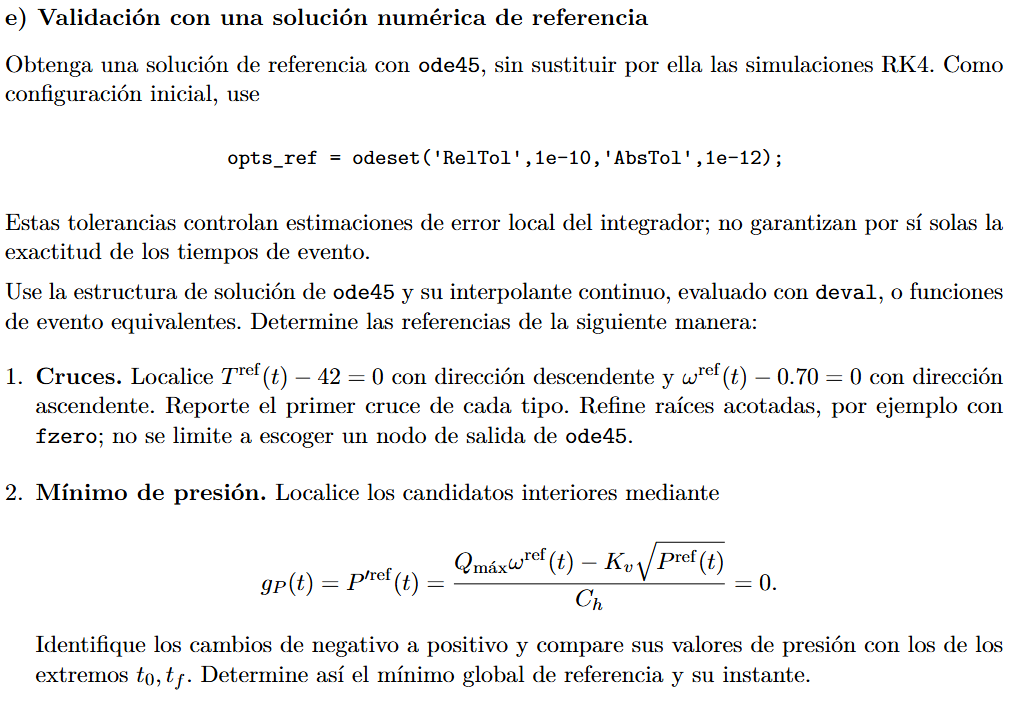

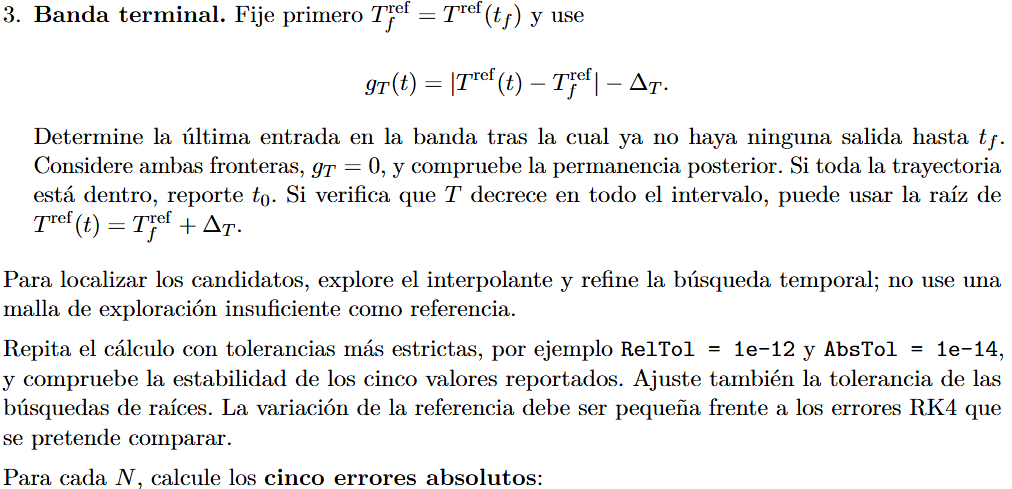

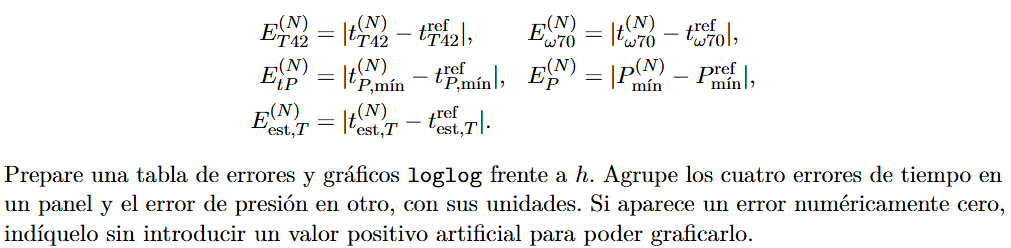

% Validación con una solución numérica de referencia y análisis de errores

tols = [1e-10 1e-12; 1e-12 1e-14];
tolx = [1e-12 1e-14];
tg = linspace(t0, tf, 20001);

tT42r = zeros(2,1); tw70r = zeros(2,1); tPminr = zeros(2,1);
Pminr = zeros(2,1); testr = zeros(2,1);

for k = 1:2
    opts = odeset('RelTol', tols(k,1), 'AbsTol', tols(k,2));
    sol = ode45(f, [t0, tf], Y0, opts);
    optz = optimset('TolX', tolx(k));

    Yg = deval(sol, tg);
    Pg = Yg(1,:); Tg = Yg(2,:); wg = Yg(3,:);

    dTg = Tg - Tumbral;
    i1 = find(dTg(1:end-1) > 0 & dTg(2:end) <= 0, 1);
    if isempty(i1), error('No hay cruce descendente de T = 42 en [t0,tf].'); end
    tT42r(k) = fzero(@(x) deval(sol, x, 2) - Tumbral, [tg(i1) tg(i1+1)], optz);

    dwg = wg - wumbral;
    i2 = find(dwg(1:end-1) < 0 & dwg(2:end) >= 0, 1);
    if isempty(i2), error('No hay cruce ascendente de w = 0.70 en [t0,tf].'); end
    tw70r(k) = fzero(@(x) deval(sol, x, 3) - wumbral, [tg(i2) tg(i2+1)], optz);

    gPg = (p.Qmax*wg - p.Kv*sqrt(Pg))/p.Ch;
    iP = find(gPg(1:end-1) < 0 & gPg(2:end) >= 0);
    cand = [t0, tf];
    for q = 1:numel(iP)
        cand(end+1) = fzero(@(x) (p.Qmax*deval(sol, x, 3) - p.Kv*sqrt(deval(sol, x, 1)))/p.Ch, ...
            [tg(iP(q)) tg(iP(q)+1)], optz);
    end
    cand = sort(cand);
    Pc = deval(sol, cand, 1);
    [Pminr(k), im] = min(Pc);
    tPminr(k) = cand(im);

    Tfin = deval(sol, tf, 2);
    bg = abs(Tg - Tfin) - DT;
    io = find(bg > 0, 1, 'last');
    if isempty(io)
        testr(k) = t0;
    else
        testr(k) = fzero(@(x) abs(deval(sol, x, 2) - Tfin) - DT, [tg(io) tg(io+1)], optz);
    end
end

t_T42_ref = tT42r(1);
t_w70_ref = tw70r(1);
t_Pmin_ref = tPminr(1);
P_min_ref = Pminr(1);
t_est_T_ref = testr(1);

fprintf('VALORES DE REFERENCIA (RelTol=1e-10, AbsTol=1e-12, TolX=1e-12)\n');

VALORES DE REFERENCIA (RelTol=1e-10, AbsTol=1e-12, TolX=1e-12)


fprintf('t_T42_ref   = %.10f s\n', t_T42_ref);

t_T42_ref   = 5.0377745316 s


fprintf('t_w70_ref   = %.10f s\n', t_w70_ref);

t_w70_ref   = 2.7773593899 s


fprintf('t_Pmin_ref  = %.10f s\n', t_Pmin_ref);

t_Pmin_ref  = 1.6549490633 s


fprintf('P_min_ref   = %.10f kPa\n', P_min_ref);

P_min_ref   = 45.9446953455 kPa


fprintf('t_est_T_ref = %.10f s\n', t_est_T_ref);

t_est_T_ref = 18.1242158757 s



dif_ref = [abs(tT42r(1)-tT42r(2)); abs(tw70r(1)-tw70r(2)); abs(tPminr(1)-tPminr(2)); ...
           abs(Pminr(1)-Pminr(2)); abs(testr(1)-testr(2))];

fprintf('\nESTABILIDAD (RelTol=1e-12, AbsTol=1e-14, TolX=1e-14)\n');


ESTABILIDAD (RelTol=1e-12, AbsTol=1e-14, TolX=1e-14)


fprintf('Diferencia t_T42   : %.4e s\n', dif_ref(1));

Diferencia t_T42   : 1.0516e-12 s


fprintf('Diferencia t_w70   : %.4e s\n', dif_ref(2));

Diferencia t_w70   : 6.8726e-11 s


fprintf('Diferencia t_Pmin  : %.4e s\n', dif_ref(3));

Diferencia t_Pmin  : 6.5952e-12 s


fprintf('Diferencia P_min   : %.4e kPa\n', dif_ref(4));

Diferencia P_min   : 1.0786e-11 kPa


fprintf('Diferencia t_est_T : %.4e s\n', dif_ref(5));

Diferencia t_est_T : 2.2240e-12 s



E_T42 = abs(tT42 - t_T42_ref);
E_w70 = abs(tw70 - t_w70_ref);
E_tP  = abs(tPmin - t_Pmin_ref);
E_P   = abs(Pmn - P_min_ref);
E_est = abs(test - t_est_T_ref);

fprintf('\nMáxima variación de la referencia: %.4e\n', max(dif_ref));


Máxima variación de la referencia: 6.8726e-11


fprintf('Menor error RK4 no nulo: %.4e\n', min([E_T42(E_T42>0); E_w70(E_w70>0); E_tP(E_tP>0); E_P(E_P>0); E_est(E_est>0)]));

Menor error RK4 no nulo: 1.6285e-05



tabla_e = table(Ns(:), hv, E_T42, E_w70, E_tP, E_P, E_est, ...
    'VariableNames', {'N','h_s','E_T42_s','E_w70_s','E_tP_s','E_Pmin_kPa','E_est_T_s'});
tabla_e.Properties.VariableUnits = {'','s','s','s','s','kPa','s'};

fprintf('\nTABLA DE ERRORES ABSOLUTOS (ITEM E)\n');


TABLA DE ERRORES ABSOLUTOS (ITEM E)


format long g
disp(tabla_e)

     N      h_s           E_T42_s                 E_w70_s                 E_tP_s                E_Pmin_kPa              E_est_T_s      
    ___    _____    ____________________    ____________________    ___________________    ____________________    ____________________

     50      0.4     0.00612555740382437     0.00196750071205409     0.0549490633220724     0.00586454397156899       0.275784124294074
    100      0.2    0.000986630315090942     0.00111856984665115     0.0549490633220724     0.00585210005058201      0.0757841242940742
    200      0.1    0.000377093736060985    0.000516409349577529     0.0450509366779275      0.0039538891165023      0.0757841242940742
    400     0.05    7.38997264679853e-05    0.000186868135585883    0.00494906332

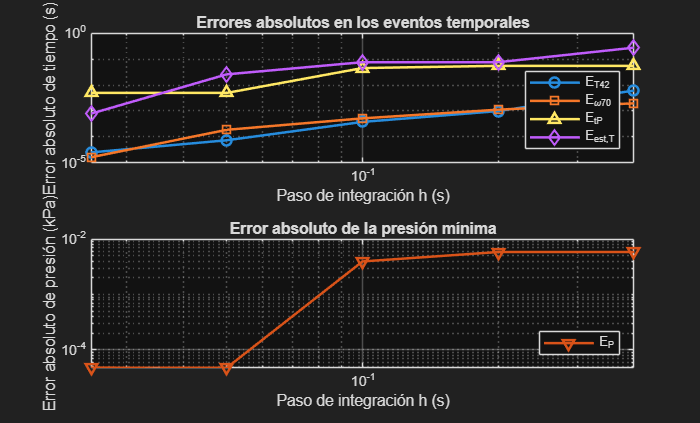

format short

Eplot = [E_T42 E_w70 E_tP E_P E_est];
if any(Eplot(:) == 0)
    disp('Hay errores exactamente cero; no se grafican en el eje logaritmico.');
end
Eplot(Eplot == 0) = NaN;

fig_e = figure('Visible', 'off');
tiledlayout(fig_e, 2, 1);

nexttile
loglog(hv, Eplot(:,1), '-o', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
loglog(hv, Eplot(:,2), '-s', 'LineWidth', 1.5, 'MarkerSize', 6);
loglog(hv, Eplot(:,3), '-^', 'LineWidth', 1.5, 'MarkerSize', 6);
loglog(hv, Eplot(:,5), '-d', 'LineWidth', 1.5, 'MarkerSize', 6);
xlabel('Paso de integración h (s)');
ylabel('Error absoluto de tiempo (s)');
title('Errores absolutos en los eventos temporales');
legend('E_{T42}', 'E_{\omega70}', 'E_{tP}', 'E_{est,T}', 'Location', 'southeast');
grid on;

nexttile
loglog(hv, Eplot(:,4), '-v', 'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0.8500 0.3250 0.0980]);
xlabel('Paso de integración h (s)');
ylabel('Error absoluto de presión (kPa)');
title('Error absoluto de la presión mínima');
legend('E_{P}', 'Location', 'southeast');
grid on;

fig_e.Visible = 'on';

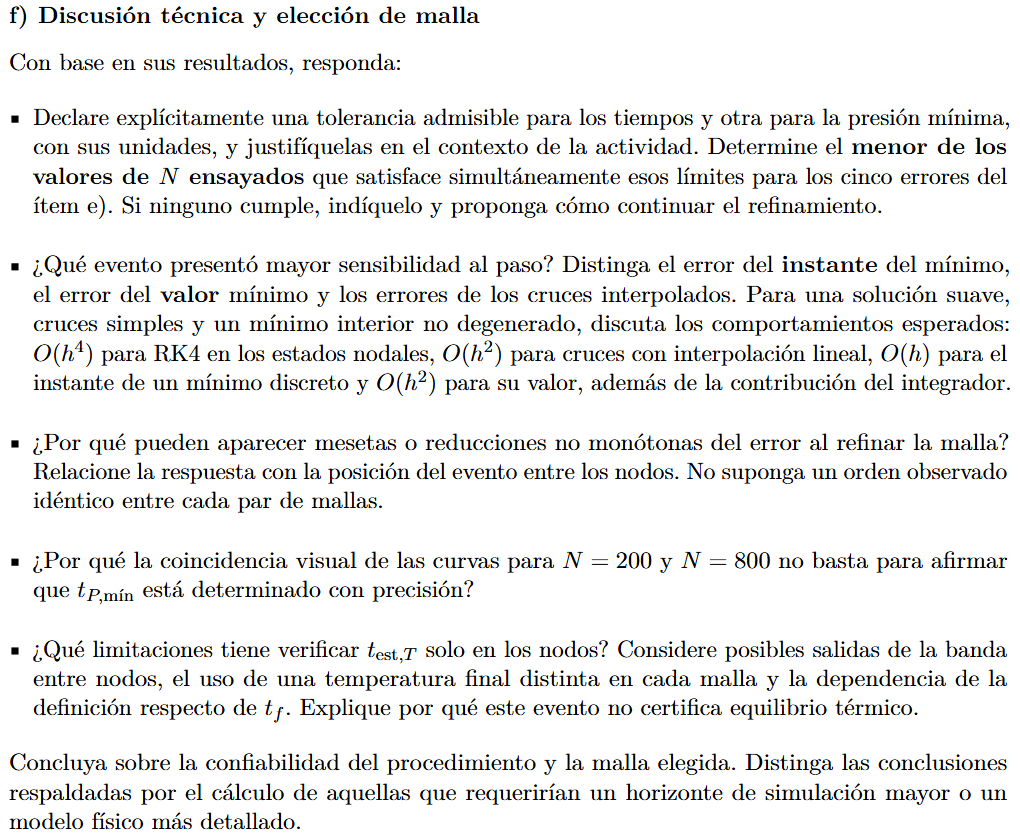

 (f) Discusión técnica y conclusiones

1era. Se establecieron tolerancias de 0.01 s para los tiempos de eventos y 0.001 kPa para la presión mínima, buscando una precisión adecuada durante el arranque. La menor malla que cumple simultáneamente los cinco criterios es N = 800 (h = 0.025 s), con un error temporal máximo de 0.004949 s y un error de presión mínima de 0.0000477 kPa.

2da. El tiempo de establecimiento térmico presentó la mayor variación absoluta, reduciendo su error de 0.275784 s a 0.000784 s. Teóricamente, RK4 presenta un error nodal O(h⁴), los cruces interpolados O(h²), el instante del mínimo discreto O(h) y su valor O(h²), además de la contribución del integrador.

3ra. Los errores dependen de la posición del evento respecto a los nodos. Por ejemplo, para N = 400 y N = 800, el error del instante de presión mínima permanece en 0.004949 s, mientras que el error de su valor aumenta ligeramente. Por ello, el refinamiento no garantiza una reducción uniforme del error ni un orden observado idéntico entre mallas.

4ta. Aunque las curvas de N = 200 y N = 800 prácticamente coinciden, sus instantes de presión mínima son 1.70 s y 1.65 s, respectivamente, frente a 1.654949 s de referencia. Esto demuestra que una coincidencia visual no garantiza precisión en la localización del mínimo.

5ta. Verificar el establecimiento térmico únicamente en los nodos no descarta salidas de la banda de ±0.5 °C entre ellos. Además, cada malla utiliza su propia temperatura final T(tf) y el resultado depende del horizonte de simulación de 20 s. Por tanto, este evento no demuestra que exista equilibrio térmico permanente.

Concluimos que...

El método RK4 permitió simular el sistema hidrotérmico manteniendo presiones positivas durante el intervalo estudiado. La comparación con ode45 respaldó la precisión de las soluciones, aunque algunos eventos presentaron errores no monótonos. Se seleccionó N = 800 por cumplir las tolerancias establecidas para los cinco errores considerados. Sin embargo, confirmar un equilibrio térmico permanente requeriría ampliar el tiempo de simulación y considerar un modelo físico más detallado.



function dY = edo_rc02(t,Y,p)
P = Y(1);  T = Y(2);  w1 = Y(3);  w2 = Y(4);
if ~(P > 0)
    error('RC02:dominio','Fuera del dominio: P = %g kPa <= 0 en t = %.6f s.',P,t);
end
dP  = (p.Qmax*w1 - p.Kv*sqrt(P))/p.Ch;
dT  = p.Qmax*w1/(p.Ch*P)*(p.Tin - T) ...
    + (p.Qgen - p.UAs*(T - p.Tamb))/(p.rho*p.cp*p.Ch*P);
dw1 = w2;
dw2 = (s_mando(t,p) - p.alpha*w2 - w1)/p.tau;
dY  = [dP; dT; dw1; dw2];
end

function s = s_mando(t,p)
s = p.s0 + p.ds*(1 - exp(-p.lam*t));
end


